# Elliptical Data with Cubic Kernel

Performs outlier detection on the example data set form the original paper with a linear kernel.

## Setup

clc;
clear all;
close all;

addpath(genpath(fileparts(which(mfilename))));

## Colors & Fonts

Create some colors for the figures

color_BLUE      = [0 0.6980 0.9333];
color_ORANGE    = [0.9333 0.4627 0];
color_GREEN     = [0 0.6980 0.1];    
color_GREY      = [0.25 0.25 0.25];    
color_RED       = [0.80 0 0];

fontSize = 10;
mSize = 8;

## Sample Dataset

rng(5);
epsilon =0.2

epsilon = 0.2000

alpha = 0.75

alpha = 0.7500

ndm = NewDataModel(ALYZCorrelationType(), ClusterContamination());
[x, ~, ~,idxOutliers] = ndm.generateDataset(1000, 2, epsilon, 20);        
y = ones(1000,1);
y(idxOutliers) = 0;
y = logical(y);
x = rZscores(x);

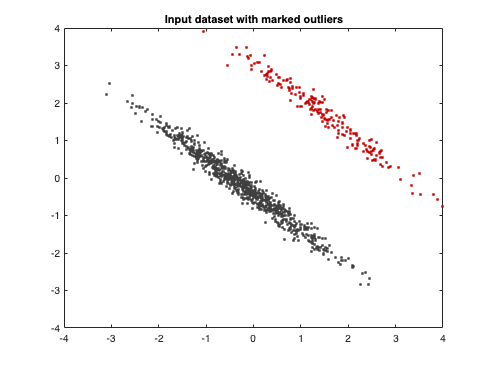

[rr, cc] = meshgrid(-5:0.1:5, -5:0.1:5);
yy=[rr(:), cc(:)];    
fig = figure(1);
plot(x(y>0, 1), x(y>0, 2), '.', 'color', color_GREY, 'MarkerSize', mSize); hold on;
plot(x(y==0, 1), x(y==0, 2), '.', 'color', color_RED, 'MarkerSize', mSize);
set(gca,'FontSize',fontSize);    
colormap bone;
set(gcf,'color','w');
ylim([-4, 4]);
title('Input dataset with marked outliers');

## Computation

kModel = PolyKernel(3);
poc = kMRCD(kModel); 
solution = poc.runAlgorithm(x, alpha);

Convergence at iteration 2, SDO
Convergence at iteration 2, SpatialRank
Convergence at iteration 7, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SDO


rho = solution.rho;
scfac = solution.scfac;

## Result

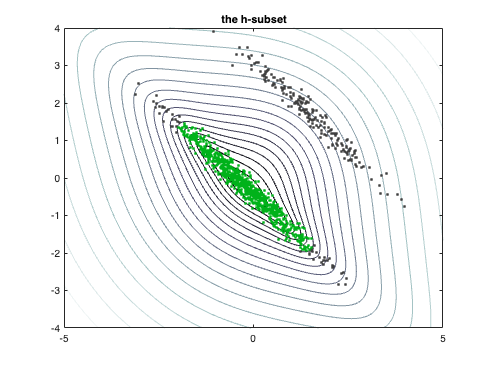

[rr, cc] = meshgrid(-5:0.1:5, -5:0.1:5);        
yy=[rr(:), cc(:)];    

Kx = kModel.compute(x(solution.hsubsetIndices, :), x(solution.hsubsetIndices, :));
nx = size(Kx,1);
Kt = kModel.compute(yy, x(solution.hsubsetIndices, :)); 
Kc = Utils.center(Kx);
Kt_c = Utils.center(Kx,Kt);
Ktt_diag = diag(kModel.compute(yy,yy)); % Precompute
Kxx = Ktt_diag - (2/nx)*sum(Kt,2) + (1/nx^2)*sum(sum(Kx));
smdMesh = (1/rho)*(Kxx - (1-rho)*scfac*sum((Kt_c/((1-rho)*scfac*Kc + nx*rho*eye(nx)).*Kt_c),2)); 

ss = logical(y);

figure(2);         
contour(rr, cc, reshape(log(smdMesh), size(rr)), 20); hold on;        
plot(x(:, 1), x(:, 2), '.', 'color', color_GREY, 'MarkerSize', mSize);
plot(x(solution.hsubsetIndices, 1), x(solution.hsubsetIndices, 2), '.', 'color', color_GREEN, 'MarkerSize', mSize);
set(gca,'FontSize',fontSize);
hold off;
colormap bone;
set(gcf,'color','w');
ylim([-4, 4]);
title('the h-subset');

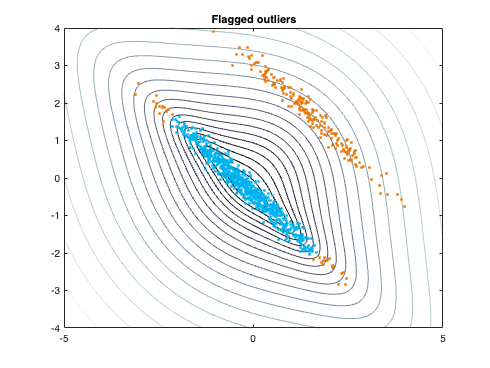


figure(3);        
contour(rr, cc, reshape(log(smdMesh), size(rr)), 20); hold on;
plot(x(:, 1), x(:, 2), '.', 'color', color_BLUE, 'MarkerSize', mSize);
plot(x(solution.flaggedOutlierIndices, 1), x(solution.flaggedOutlierIndices, 2), '.', 'color', color_ORANGE, 'MarkerSize', mSize);
hold off;
colormap bone;
set(gcf,'color','w');
ylim([-4, 4]);
set(gca,'FontSize',fontSize);
title('Flagged outliers');